%% --- Linkage Simulation Controller ---
clc; clear; close all;

disp('Select simulation type:')

Select simulation type:


disp('1. Full 3D linkage animation (colored bars)')

1. Full 3D linkage animation (colored bars)


disp('2. Kinematic diagram (lines and joints)')

2. Kinematic diagram (lines and joints)


Running kinematic diagram animation...


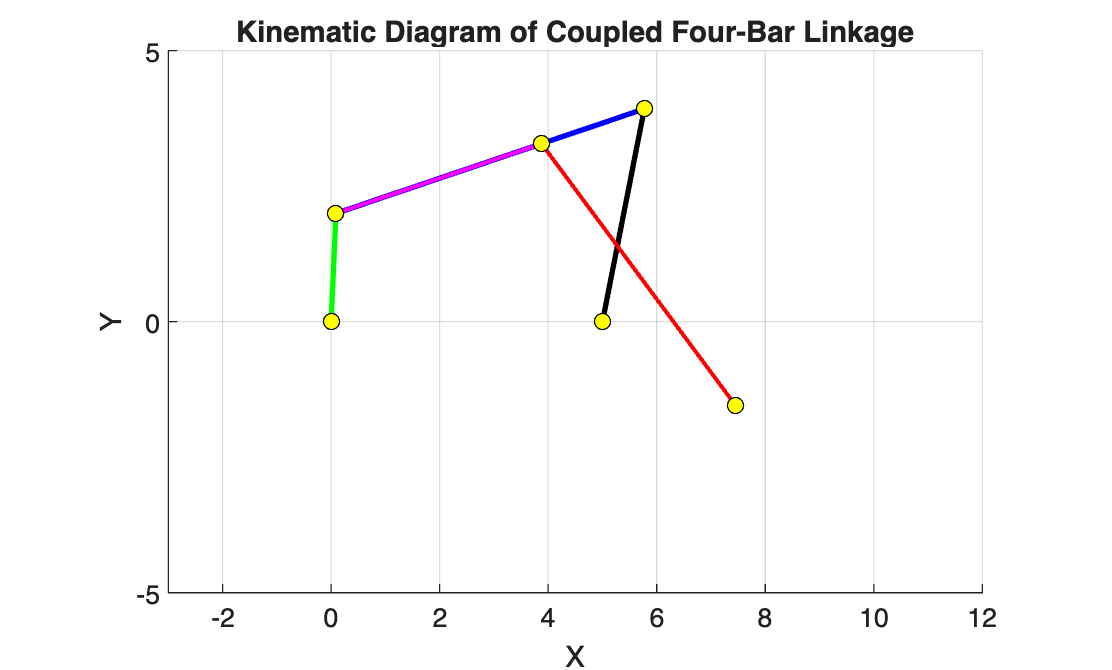

mode = input('Enter choice (1 or 2): ');

switch mode
    case 1
        disp('Running full linkage animation...');
        drawframe(1);
        for k = 1:150
            drawframe(2);
            pause(0.04);
        end

    case 2
        disp('Running kinematic diagram animation...');
        drawframe_kinematic(1);
        for k = 1:200
            drawframe_kinematic(2);
            pause(0.04);
        end
end


%% --- Function: drawframe (Colored 3D Style) ---
function drawframe(f)
    if nargin < 1
        error('Not enough input arguments.');
    end

    persistent L1 L2 L3 L4 L5 L6 L7 L8 t2 t3 t4 t5 t6 ...
        Bar2 Bar3 Bar4 Bar5 Bar6 f1 f2

    if f == 1
        clf; figure(1); hold on; axis equal;
        title('Four-bar + Coupled Linkage Simulation');
        xlabel('X'); ylabel('Y');
        L1=5; L2=2; L3=6; L4=4; L5=6; L6=4; L7=5; L8=1;

        f1=@(t2,t)(L2*cos(t2)-(L1+L4*cos(t)))^2+(L2*sin(t2)-L4*sin(t))^2-L3^2;
        f2=@(x5,y5,T)[x5+L5*cos(T(1))-(L1+L7+0.9*L6*cos(T(2)));
                       y5+L5*sin(T(1))-(L8+0.9*L6*sin(T(2)))];
        t=linspace(0,2*pi,100);
        wclr=0.8*[1 1 1];
        fill(1.15*cos(t),1.15*sin(t),wclr);
        fill(L1+1.15*cos(t),1.15*sin(t),wclr);
        fill((L1+L7)+1.15*cos(t),L8+1.15*sin(t),wclr);

        t4=acos(((L2+L3)^2-L1^2-L4^2)/(2*L1*L4));
        t2=asin(sin(t4*L4/(L2+L3)));
        c2=cos(t2); s2=sin(t2);
        x3=L2*c2; y3=L2*s2;
        c4=cos(t4); s4=sin(t4);
        t3=atan2(L4*s4-L2*s2,L1+L4*c4-L2*c2);
        x5=L2*c2+(2/3)*((L1+L4*c4)-L2*c2);
        y5=L2*s2+(2/3)*(L4*s4-L2*s2);

        opts=optimoptions('fsolve','Display','off');
        t56=fsolve(@(T)f2(x5,y5,T),[1.5*pi;1.5*pi],opts);
        t5=t56(1); t6=t56(2);

        brown=[206,179,140]/255;
        Bar2=BarMaker(L2,'g',0); Bar2.Rotate(t2);
        Bar3=BarMaker(L3,'b',[0,0.45]); Bar3.Rotate(t3); Bar3.Trans([x3,y3]);
        Bar4=BarMaker(L4,'g',0); Bar4.Rotate(t4); Bar4.Trans([L1,0]);
        Bar5=BarMaker(L5,brown,0.3); Bar5.Rotate(t5); Bar5.Trans([x5,y5]);
        Bar6=BarMaker(L6,'r',0); Bar6.Rotate(t6); Bar6.Trans([L1+L7,L8]);

        axis([-2.6,11.4,-5,5]);
        drawnow;
    else
        t2=t2+2*pi/48;
        c2=cos(t2); s2=sin(t2);
        x3=L2*c2; y3=L2*s2;
        t4=fzero(@(t)f1(t2,t),t4);
        c4=cos(t4); s4=sin(t4);
        t3=atan2(L4*s4-L2*s2,L1+L4*c4-L2*c2);
        x5=L2*c2+(2/3)*((L1+L4*c4)-L2*c2);
        y5=L2*s2+(2/3)*(L4*s4-L2*s2);
        opts=optimoptions('fsolve','Display','off');
        t56=fsolve(@(T)f2(x5,y5,T),[t5;t6],opts);
        t5=t56(1); t6=t56(2);
        Bar2.Rotate(t2);
        Bar3.Rotate(t3); Bar3.Trans([x3,y3]);
        Bar4.Rotate(t4);
        Bar5.Rotate(t5); Bar5.Trans([x5,y5]);
        Bar6.Rotate(t6);
        drawnow;
    end
end

%% --- Function: BarMaker ---
function B=BarMaker(L,clr,F)
    if nargin < 3, F = 0; end
    t1=pi/2+linspace(0,pi,20); t2=t1+pi;
    s1=sin(t1); s2=sin(t2); c1=cos(t1); c2=cos(t2);
    Xl=[0.5*c1,L+0.5*c2]; Yl=[0.5*s1,0.5*s2]; X=Xl; Y=Yl;
    Xl=[Xl,Xl(1)]; Yl=[Yl,Yl(1)];
    for n=1:numel(F)
        f=F(n);
        X=[X,f*L,f*L+0.3*[c1,c2],f*L];
        Y=[Y,0.5,0.3*[s1,s2],0.5];
    end
    ax=gca; H=hgtransform('Parent',ax); K=hgtransform('Parent',H);
    B.line=plot(Xl,Yl,'k','Parent',K);
    B.fill=fill(X,Y,clr,'EdgeColor','none','Parent',K);
    B.Rotate=@(t)set(K,'Matrix',makehgtform('zrotate',t));
    B.Trans=@(p)set(H,'Matrix',makehgtform('translate',[p,0]));
end

%% --- Function: drawframe_kinematic (Simplified Diagram) ---
function drawframe_kinematic(f)
    persistent L1 L2 L3 L4 L5 L6 L7 L8 t2 t3 t4 t5 t6 f1 f2 hLinks hJoints
    if f==1
        clf; figure(1); hold on; axis equal;
        title('Kinematic Diagram of Coupled Four-Bar Linkage');
        xlabel('X'); ylabel('Y'); grid on;
        L1=5; L2=2; L3=6; L4=4; L5=6; L6=4; L7=5; L8=1;
        f1=@(t2,t)(L2*cos(t2)-(L1+L4*cos(t)))^2+(L2*sin(t2)-L4*sin(t))^2-L3^2;
        f2=@(x5,y5,T)[x5+L5*cos(T(1))-(L1+L7+0.9*L6*cos(T(2)));
                       y5+L5*sin(T(1))-(L8+0.9*L6*sin(T(2)))];
        t4=acos(((L2+L3)^2-L1^2-L4^2)/(2*L1*L4));
        t2=asin(sin(t4*L4/(L2+L3)));
        c2=cos(t2); s2=sin(t2);
        x3=L2*c2; y3=L2*s2;
        c4=cos(t4); s4=sin(t4);
        t3=atan2(L4*s4-L2*s2,L1+L4*c4-L2*c2);
        x5=L2*c2+(2/3)*((L1+L4*c4)-L2*c2);
        y5=L2*s2+(2/3)*(L4*s4-L2*s2);
        opts=optimoptions('fsolve','Display','off');
        t56=fsolve(@(T)f2(x5,y5,T),[1.5*pi;1.5*pi],opts);
        t5=t56(1); t6=t56(2);
        A=[0,0]; B=[L1,0]; F=[L1+L7,L8];
        C=[x3,y3]; D=[L1+L4*c4,L4*s4]; E=[x5,y5];
        G=[L1+L7+0.9*L6*cos(t6),L8+0.9*L6*sin(t6)];
        hLinks(1)=plot([A(1) C(1)], [A(2) C(2)], 'g', 'LineWidth', 2);
        hLinks(2)=plot([C(1) D(1)], [C(2) D(2)], 'b', 'LineWidth', 2);
        hLinks(3)=plot([B(1) D(1)], [B(2) D(2)], 'k', 'LineWidth', 2);
        hLinks(4)=plot([C(1) E(1)], [C(2) E(2)], 'm', 'LineWidth', 1.5);
        hLinks(5)=plot([E(1) G(1)], [E(2) G(2)], 'r', 'LineWidth', 1.5);
        Pts=[A;B;C;D;E;F;G];
        hJoints=plot(Pts(:,1),Pts(:,2),'ko','MarkerFaceColor','y','MarkerSize',6);
        axis([-3 12 -5 5]); drawnow;
    else
        t2=t2+2*pi/48; c2=cos(t2); s2=sin(t2);
        x3=L2*c2; y3=L2*s2;
        t4=fzero(@(t)f1(t2,t),t4);
        c4=cos(t4); s4=sin(t4);
        t3=atan2(L4*s4-L2*s2,L1+L4*c4-L2*c2);
        x5=L2*c2+(2/3)*((L1+L4*c4)-L2*c2);
        y5=L2*s2+(2/3)*(L4*s4-L2*s2);
        opts=optimoptions('fsolve','Display','off');
        t56=fsolve(@(T)f2(x5,y5,T),[t5;t6],opts);
        t5=t56(1); t6=t56(2);
        A=[0,0]; B=[L1,0];
        C=[x3,y3]; D=[L1+L4*c4,L4*s4]; E=[x5,y5];
        G=[L1+L7+0.9*L6*cos(t6),L8+0.9*L6*sin(t6)];
        set(hLinks(1),'XData',[A(1) C(1)],'YData',[A(2) C(2)]);
        set(hLinks(2),'XData',[C(1) D(1)],'YData',[C(2) D(2)]);
        set(hLinks(3),'XData',[B(1) D(1)],'YData',[B(2) D(2)]);
        set(hLinks(4),'XData',[C(1) E(1)],'YData',[C(2) E(2)]);
        set(hLinks(5),'XData',[E(1) G(1)],'YData',[E(2) G(2)]);
        Pts=[A;B;C;D;E;G];
        set(hJoints,'XData',Pts(:,1),'YData',Pts(:,2));
        drawnow;
    end
end
